problem 1-part 1

initialize the parameters 

% Define your parameters
theta = [0.3, -0.5, 0.5, 0.2, 0.4];
u_mean = 1;
u_std = 0.12;

% Initialize a matrix to store all the Y values
Y_all = zeros(100, 100);


% Generate half of u values from N(u_mean, u_std)
half_size = 100/2;
u_half1 = -u_mean + sqrt(u_std) * randn(half_size, 1);

% Generate half of u values from N(-u_mean, u_std)
u_half2 = u_mean + sqrt(u_std) * randn(half_size, 1);
u = [u_half1; u_half2];

% Generate X matrix
X = [ones(100,1), u, u.^2/2, u.^3/3, u.^4/4];

create Y_all 100*500 matrix based on X


for i = 1:500  %for this part we will make this 1000
    % Generate noise N(mu, sigma)
    % N = 0.1 * randn(100, 1); % noise for 0.01 variance
      N = randn(100, 1);
    % Calculate Y
    Y = X * theta' + N;
    
    % Store Y in the matrix
    Y_all(:, i) = Y;
end

Least sqaure method

% Perform LS estimation 
theta_hat_LS = (X' * X)^-1 * X' * Y_all;

calculated Y_hat_LS and sort it

 % Calculate Y_hat_LS
 Y_hat_LS = X * theta_hat_LS;

% Sort X
[X_sorted, idx] = sort(X(:, 2)); % Sorting according to the second column (u)
%X_sorted = X(idx, :);
 
% Sort Y according to the indexes of sorted X
Y_sorted_LS = Y_hat_LS(idx,:);
 
% Calculate the average of each column of Y_sorted
Y_avg_LS = mean(Y_sorted_LS, 2); 

calculate the std

std_along_columns_LS = (std(Y_sorted_LS, 0, 2));

plot  for LS

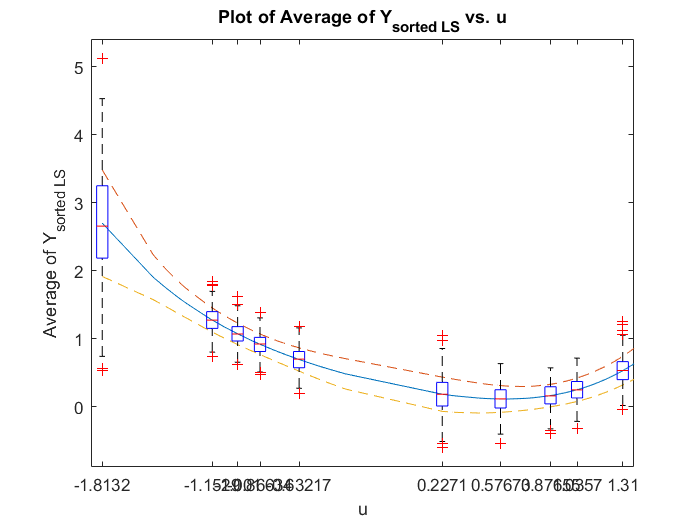

% Plot the average of Y_sorted with respect to u
figure;
plot(X_sorted, Y_avg_LS, '-');
xlabel('u');
ylabel('Average of Y_{sorted LS}');
title('Plot of Average of Y_{sorted LS} vs. u');
hold on
plot(X_sorted, Y_avg_LS + std_along_columns_LS , '--');
plot(X_sorted, Y_avg_LS - std_along_columns_LS , '--');
%scatter(u(idx, :),Y_sorted)
%errorbar(u(idx(1:10:end), :), Y_sorted(1:10), std_along_columns(1:10), 'o-');
% boxplot(Y_sorted(1:10, :).')
% xticklabels(X_sorted.');
% Create the boxplot
hBoxPlot = boxplot(Y_sorted_LS(1:10:100, :).', 'Positions', X_sorted(1:10:100));

% Set the x-tick labels to correspond to the sorted X values
set(gca, 'xticklabel', arrayfun(@num2str, X_sorted(1:10:100), 'UniformOutput', false));

%xticks(X_sorted(1:10, :));
hold off